Changing the current folder

cd C:\Users\washi\Documents\GitHub\N2-Propulsion\'Test Stand'\

READING DATA FROM EXCEL

windowSize = 32;
b = (1/windowSize)*ones(1, windowSize);
a = 1;

t6= readtable('monday4.csv')

t6 = 10394×1 table
    Var1
    ____

    0.64
    0.07
    -1.6
    -1.2
     0.1
     0.9
     0.9
     0.3
     0.1
    -0.1
     0.7
     0.7
     1.1
    -0.6
    -1.2
    -0.7


t6 = table2array(t6);
y = filter(b, a ,t6)

y =     0.0200
    0.0222
   -0.0278
   -0.0653
   -0.0622
   -0.0341
   -0.0059
    0.0034
    0.0066
    0.0034


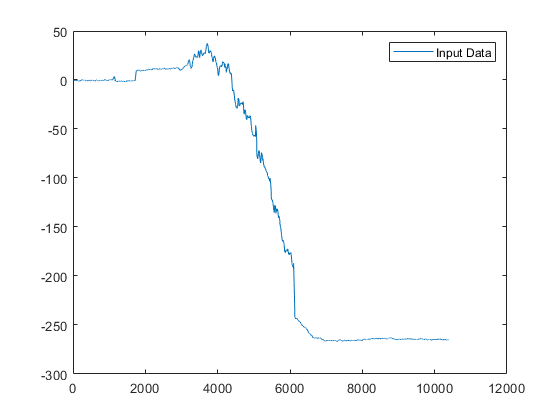

%plot(t6)
%hold on
plot(y)
legend('Input Data', 'Filtered data')

max(y)

ans = 37.5000